clc
clear
N = 1024; %% Length of signal
t = linspace(-10,10,N);

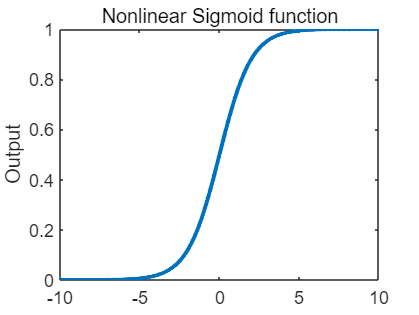

sigmoid = 1./(1+exp(-t)); %% sigmoid
plot(t, sigmoid,'LineWidth',2)
ylabel('Output')
title('Nonlinear Sigmoid function')

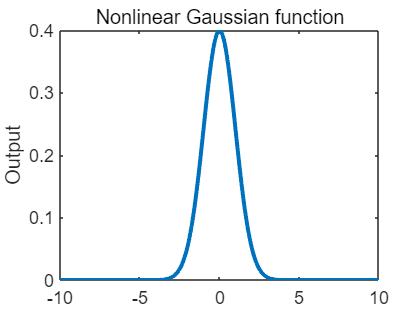


sigma0 = 1; %% variance
mu0 = 0; %% mean
gaussian = 1/sqrt(2*pi*sigma0^2) * exp(-(t - mu0).^2/(2*sigma0^2)); %% gaussian
plot(t, gaussian,'LineWidth',2)
ylabel('Output')
title('Nonlinear Gaussian function')

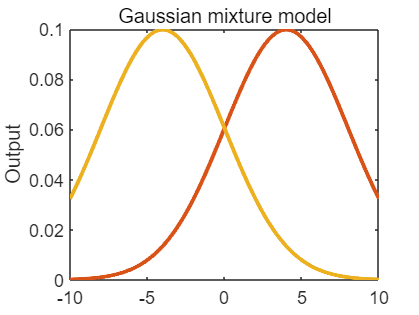


%% Gaussian mixture
sigma = randi([1,5], 1, 3); %% random variance for three order
mu = randi([-5,5], 1, 3); %% random mean for three order

for n = 1:3
gmm(n,:) = 1/(sigma(n)*sqrt(2*pi))*exp((-1/2)*((t - mu(n)).^2./(sigma(n)^2)));
plot(t,gmm(n,:),'LineWidth',2)
ylabel('Output')
title('Gaussian mixture model')
hold on
xlim([-10.0 10.0])
end
hold off

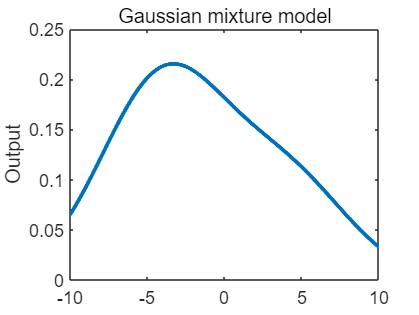


gmm_all = sum(gmm,1); %% Gaussian mixture output
plot(t, gmm_all,'LineWidth',2)
ylabel('Output')
title('Gaussian mixture model')

## Volterra series and traning

L = 8; %% memory length
loopnum = 1000; %% iteration number
mu = 0.001;

%% intial kernel parameter and input data
X = rand(1,N);

## one order

% mse = zeros(1,loopnum);
% for i = 1:loopnum
%     for j=1:N
%         X_shift = circshift(X,-j+1,2);
%         for l = 1:L
%             X_in = circshift(X_shift,l-1,2);
%             x(l) = X_in(1);
%         end
%         Y(j) = sum(w.*x);
%         e(j) = sigmoid(j)-Y(j); % error calculate
%         w = w + e(j)*mu*2; % parameter renewal
%         Y(j) = sum(w.*x);
%     end
% end
% plot(1:loopnum,mse)

w = ones(N,L);
mse = zeros(1,loopnum);
for i = 1:loopnum
    for j=1:N
        X_shift = circshift(X,-j+1,2);
        for l = 1:L
            X_in = circshift(X_shift,l-1,2);
            x(l,j) = X_in(1);
        end
        Y(j) = sum(w(j,:)*x(:,j));
        e(j) = gaussian(j)-Y(j); % error calculate
        w(j,:) = w(j,:) + e(j)*mu*2; % parameter renewal
        Y(j) = sum(w(j,:)*x(:,j));
    end
    mse(i) = sum(abs(e.^2))/N;
end

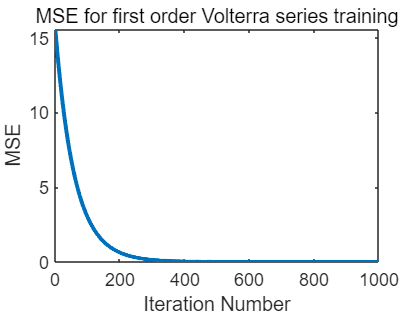

plot(1:loopnum,mse,'LineWidth',2)
xlabel('Iteration Number')
ylabel('MSE')
title('MSE for first order Volterra series training')

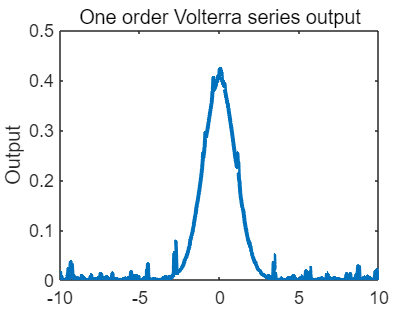

plot(t,Y,'LineWidth',2)
ylabel('Output')
title('One order Volterra series output')

%% intial kernel and input data
X2 = rand(1,N);
w2 = ones(N,L^2);
mse2 = zeros(1,loopnum);
%% two order volterra
for i = 1:loopnum
    for j=1:N
        X2_shift = circshift(X2,-j+1,2);
        for l = 1:L^2
            index = fix((l-1)/L);
            if index<1
                X2_in = X2_shift.*circshift(X2_shift,l-1,2);
                x2(l,j) = X2_in(1);
            elseif index >= 1
                X2_shift2 = circshift(X_shift,-index*L,2);
                X2_in = X2_shift2.*circshift(X_shift,l-1,2);
                x2(l,j) = X2_in(1);
            end
        end
        Y2(j) = sum(w2(j,:)*x2(:,j));
        e2(j) = gaussian(j)-Y2(j); % error calculate
        w2(j,:) = w2(j,:) + e2(j)*mu*2; %parameter renewal
        Y2(j) = sum(w2(j,:)*x2(:,j));
    end
    mse2(i) = sum(abs(e2).^2)/N;
end


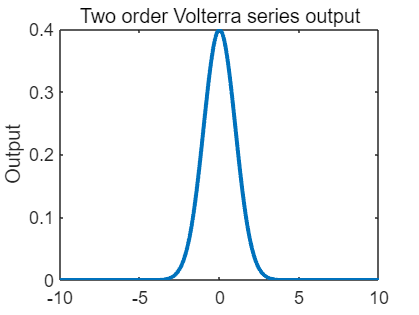

plot(t,Y2,'LineWidth',2)
ylabel('Output')
title('Two order Volterra series output')

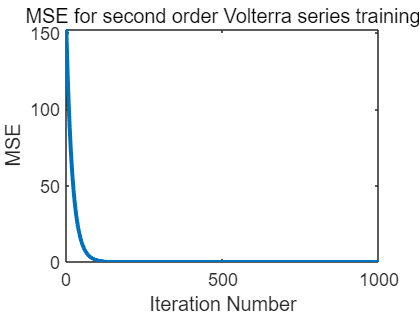

plot(1:loopnum,mse2,'LineWidth',2)
xlabel('Iteration Number')
ylabel('MSE')
title('MSE for second order Volterra series training')

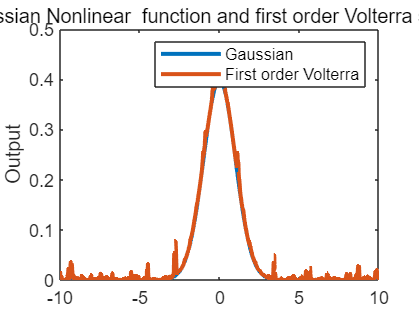

% plot(t, gaussian,'LineWidth',2)
% hold on
% plot(t,Y,'LineWidth',2)
% ylabel('Output')
% title('Ideal Gaussian Nonlinear  function and first order Volterra series output')
% legend('Gaussian','First order Volterra')

% plot(1:loopnum,mse,'LineWidth',2)
% hold on
% plot(1:loopnum,mse2,'LineWidth',2)
% ylim([0,50])
% xlabel('Iteration Number')
% ylabel('MSE')
% title('MSE comparison for First and Second-order Volterra series training')
% legend('First-order Volterra','Second order Volterra')